# get compartments of SVR & Transmission rates

clear;
addressnew={'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
%addressnew={'_1Base'};
%addressnew={'_5Base+AH+T+O+H_NPI_5','_5Base+AH+T+O+H_NPI_10','_5Base+AH+T+O+H_NPI_15',}


# gain_weightings_

Model_scripts = {'_1Base','_2Base+AH','_2Base+H','_2Base+O','_2Base+T','_3Base+AH+H','_3Base+AH+O','_3Base+AH+T','_3Base+O+H','_3Base+T+H',...
    '_3Base+T+O','_4Base+AH+O+H','_4Base+AH+T+H','_4Base+AH+T+O','_4Base+T+O+H','_5Base+AH+T+O+H'};
addressnew = Model_scripts;
WIS_Short=[];WIS_Long=[];
for number = 16:length(addressnew)
       cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")

     cd (addressnew{number});
     load('cross_WIS.mat');WIS4=WIS4(1:8,1:8);
     WIS_Short(number,:,:) = WIS1;
     WIS_Long(number,:,:)  = WIS4;
     WIS11 = sort(WIS1(:));
     Mean_Short(number,:)  = mean(mean(WIS11(2:end-1)));
     WIS44 = sort(WIS4(:));
     Mean_Long(number,:)   = mean(mean(WIS44(2:end-1)));
     Mean_year_Short(number,:)  = mean(WIS1);
     Mean_year_Long(number,:)   = mean(WIS4);
end
% ensemble mean
model_number={[1],[2:5],[6:11],[12:15],[16]};
for ENmodel=1:5
  Ensemble_Short_mean (ENmodel)  = mean (Mean_Short(model_number{ENmodel}));
  Ensemble_Long_mean (ENmodel)  = mean (Mean_Long(model_number{ENmodel}));
  Ensemble_Short{ENmodel} =   WIS_Short(model_number{ENmodel},:,:);
  Ensemble_Long{ENmodel}  = WIS_Long(model_number{ENmodel},:,:);

yearlong_CF        =[2012,2013,2014,2015,2016,2017,2018,2019];
EN_valueslong_CF   = [7,28,42,28,7];
% yearlong_P       = [2015,2016,2017,2018,2019];% EN_valueslong_P  = [5,20,30,20,5];
EN_valueslong_P  = [7,28,42,28,7];%[7,28,28,28,7];
yearlong_P = [2016,2017,2018,2019,2020,2021,2022,2023];
Ranks_short_P=[];Ranks_Long_P=[];

Ranks_Long_CF{ENmodel}  = Mean_year_Long(model_number{ENmodel},:);
Ranks_Long_P{ENmodel}  = Mean_year_Long(model_number{ENmodel},:);

[~,C1L_CF]=sort(Ranks_Long_CF{ENmodel}(:));[~,F1L_CF]=sort(C1L_CF(:)); Ranks_Long_CF{ENmodel}=reshape(F1L_CF,length(model_number{ENmodel}),8);
[~,C1L_P]=sort(Ranks_Long_P{ENmodel}(:));[~,F1L_P]=sort(C1L_P(:)); Ranks_Long_P{ENmodel}=reshape(F1L_P,length(model_number{ENmodel}),8);

for col=1:length(yearlong_CF)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_CF{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_CF(ENmodel),Ranks_Long_CF{ENmodel}(row,col));
    end
end
for col=1:length(yearlong_P)
    for row=1:numel(Model_scripts(model_number{ENmodel}))
        Weights_long_P{ENmodel}(row,col) = rank_order_centroid_weighting(EN_valueslong_P(ENmodel),Ranks_Long_P{ENmodel}(row,col));
    end
end
sum(sum(Weights_long_CF{ENmodel}))
sum(sum(Weights_long_P{ENmodel}))
end

ans = 1

ans = 1

ans = 1

ans = 1

ans = 1.0000

ans = 1.0000

ans = 1

ans = 1

ans = 1

ans = 1

# get data for ensemble transmission rates 

model_number={[1],[2:5],[6:11],[12:15],[16]};%{[1],[2:5],[6:9],[10:13],[14]};%
EN_valueslong_CF   = [7,28,28,28,7];
yearlong_CF        =[2012,2013,2014,2015,2016,2017,2018];

EN_valueslong_P  = [7,28,42,28,7];%[5,20,30,20,5];
yearlong_P       = [2014,2015,2016,2017,2018,2019,2020];%[2016,2017,2018,2019,2020];
for ENmodel = 1:5
N = 10000;
R_newPI_Long{ENmodel}=[];
R_newPI_LongCF{ENmodel}=[];
R_newPI_LongCF_F{ENmodel}=[];
P_newPI_Long{ENmodel}=[];

for row=1:numel(Model_scripts(model_number{ENmodel}))
    cd('E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal')
    cd(Model_scripts{model_number{ENmodel}(row)});
    for col=1:length(yearlong_CF)
        load(sprintf('Re_%d.mat',yearlong_CF(col)));
        ReR =ReR';ReC2 =ReC2';ReC1 =ReC1';
        R_newPI_Long{ENmodel}    = 1.0*bootstrap_predict_interval(R_newPI_Long{ENmodel}, ReR(1:N,1:394),Weights_long_CF{ENmodel}(row,col));
        %R_newPI_Long{ENmodel}    = R_newPI_Long{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReR(1:394,1:N);
        R_newPI_LongCF{ENmodel}    = 1.0*bootstrap_predict_interval(R_newPI_LongCF{ENmodel}, ReC1(1:N,1:394),Weights_long_CF{ENmodel}(row,col));
        %R_newPI_LongCF{ENmodel}  = R_newPI_LongCF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReC1(1:394,1:N);
        R_newPI_LongCF_F{ENmodel}    = 1.0*bootstrap_predict_interval(R_newPI_LongCF_F{ENmodel}, ReC2(1:N,1:394),Weights_long_CF{ENmodel}(row,col));
        %R_newPI_LongCF_F{ENmodel}  = R_newPI_LongCF_F{ENmodel} + Weights_long_CF{ENmodel}(row,col).*ReC2(1:394,1:N);       
    end
    for col=1:length(yearlong_P)
        load(sprintf('Re_%d.mat',yearlong_P(col)), 'ReR1');
        ReR1=ReR1';
        P_newPI_Long{ENmodel}    = 1.0*bootstrap_predict_interval(P_newPI_Long{ENmodel}, ReR1(1:N,1:394),Weights_long_P{ENmodel}(row,col));
%         P_newPI_Long{ENmodel}    = P_newPI_Long{ENmodel} + Weights_long_P{ENmodel}(row,col).*ReR1(1:394,1:N);
    end
end
end

# ** get data for ensemble susceptibility**

for ENmodel =1:5
for row=1:numel(Model_scripts(model_number{ENmodel}))
    cd("E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal")
    cd(Model_scripts{model_number{ENmodel}(row)});
N = 2000;
R_newPI_LongS{ENmodel}=zeros(N,394);%R_newPI_LongV{ENmodel}=zeros(N,394);R_newPI_LongR{ENmodel}=zeros(N,394);
R_newPI_LongCFSF{ENmodel}=zeros(N,394);%R_newPI_LongCFVF{ENmodel}=zeros(N,394);R_newPI_LongCFRF{ENmodel}=zeros(N,394);
R_newPI_LongCFS{ENmodel}=zeros(N,394);%R_newPI_LongCFV{ENmodel}=zeros(N,394);R_newPI_LongCFR{ENmodel}=zeros(N,394);
P_newPI_LongS{ENmodel}=zeros(N,394);%P_newPI_LongV{ENmodel}=zeros(N,394);P_newPI_LongR{ENmodel}=zeros(N,394);
    for col=1:length(yearlong_CF)
        load(sprintf('SRV_Comparetements_%d.mat',yearlong_CF(col)));
%         R_newPI_LongS{ENmodel}    = R_newPI_LongS{ENmodel} + Weights_long_CF{ENmodel}(row,col).*(CSR(1:N,3627:4020)+CVR(1:N,3627:4020));
        R_newPI_LongS{ENmodel} = bootstrap_predict_interval(R_newPI_LongS{ENmodel},(CSR(1:N,3627:4020)+CVR(1:N,3627:4020)),Weights_long_CF{ENmodel}(row,col));
%         R_newPI_LongCFSF{ENmodel}  = R_newPI_LongCFSF{ENmodel} + Weights_long_CF{ENmodel}(row,col).*(CSCF(1:N,3627:4020)+CVCF(1:N,3627:4020));
        R_newPI_LongCFSF{ENmodel} = bootstrap_predict_interval(R_newPI_LongCFSF{ENmodel},(CSCF(1:N,3627:4020)+CVCF(1:N,3627:4020)),Weights_long_CF{ENmodel}(row,col));
%         load(sprintf('SRV_Comparetements_CF_%d.mat',yearlong_CF(col)));
%         R_newPI_LongCFS{ENmodel}  = R_newPI_LongCFS{ENmodel} + Weights_long_CF{ENmodel}(row,col).*(CSCF(1:N,3627:4020)+CVCF(1:N,3627:4020));
    end
    for col=1:length(yearlong_P)
        load(sprintf('SRV_Comparetements_%d.mat',yearlong_P(col)),'CSR','CVR','CRR');
%         P_newPI_LongS{ENmodel}    = P_newPI_LongS{ENmodel} + Weights_long_P{ENmodel}(row,col).*(CSR(1:N,end-393:end)+CVR(1:N,end-393:end));
        P_newPI_LongS{ENmodel} = bootstrap_predict_interval(P_newPI_LongS{ENmodel},(CSR(1:N,end-393:end)+CVR(1:N,end-393:end)),Weights_long_P{ENmodel}(row,col));
    end
end
end


# Plot_sensitivity_with_transmission_rate_and_susceptibility

close all;
figure();ha1 =tight_subplot(2,2,0.1,0.1,0.1);
figure();ha2 =tight_subplot(2,2,0.1,0.1,0.1);
Name = {'(a)','(b)','(c)','(d)','(e)'};
for ENmodel = 1:4
axes(ha1(ENmodel));hold on;
F_day1=1:394;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',18);
ylabel(sprintf('Susceptibility'));
set(get(gca,'YLabel'),'FontSize',24);
set(get(gca,'XLabel'),'FontSize',24);
set(gca,'xtick',[1:90:394]);
% set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'});
xlim([1 365]);ylim([0 1.3]);
set(gca,'ytick',[0,0.2,0.4,0.6,0.8,1.0,1.2,1.4,1.6]);
set(gca,'yticklabel',{'0','0.2','0.4','0.6','0.8','1.0','1.2','1.4','1.6'});set(legend,'color','none','Box', 'on'); 

[beta2,day1,meanbeta2]= modelCI(F_day1,R_newPI_LongCF{ENmodel}');
p2(ENmodel) = plot (F_day1,meanbeta2,'LineWidth',1.5,'Color',[0.85,0.33,0.10]);
[beta3,day1,meanbeta3]= modelCI(F_day1,R_newPI_LongCF_F{ENmodel}');
p3(ENmodel)=plot (F_day1,meanbeta3,'LineWidth',1.5,'Color',[0.39,0.83,0.07]);
[beta1,day1,meanbeta]= modelCI(F_day1,R_newPI_Long{ENmodel}');
p1(ENmodel) = plot (F_day1,meanbeta,'LineWidth',1.5,'color',[0.07,0.62,1.00]);
H_F1=fill(day1,beta1,[0.07,0.62,1.00],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
H_F1=fill(day1,beta2,[0.85,0.33,0.10],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
H_F1=fill(day1,beta3,[0.39,0.83,0.07],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});

ylabel('R_e');set(legend,'color','none','Box', 'on'); 
plot([39 39],[0 0.95],':','color',[0 0 0],'LineWidth',1);
text(75,0.95,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',12,'FontName','Times New Roman');
set(gca,'xtick',[1:182:365]);
set(gca,'xticklabel',{'Jan 2020','Jul 2020','Jan 2021'},'XTickLabelRotation',0);
plotarrow(39,70,0.95,0.95);box_off;
text(7,1.2,Name(ENmodel),"FontSize",30,'FontName','Times New Roman')

legend([p1(ENmodel),p2(ENmodel),p3(ENmodel)],'PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','FontSize',10,'color','none','Location','northeast');

% 
axes(ha2(ENmodel));hold on;F_day1=1:394;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',18);
set(get(gca,'YLabel'),'FontSize',24);
set(get(gca,'XLabel'),'FontSize',24);
set(gca,'xtick',[28:90:394]);
ylabel('R_e');set(legend,'color','none','Box', 'on'); 
% set(gca,'xticklabel',{'Jun 2023', 'Sep 2023', 'Dec 2023', 'Mar 2024', 'Jun 2024'});
xlim([28 394]);
[beta1,day1,meanbeta]= modelCI(F_day1,P_newPI_Long{ENmodel}');
plot (F_day1,meanbeta,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
H_F1=fill(day1,beta1,[0.39,0.83,0.07],'FaceAlpha',0.2);hold on;set(H_F1,{'LineStyle'},{'none'});
% ylabel('\beta(t)');ylim([0 0.45]);
set(gca,'ytick',[0,0.2,0.4,0.6,0.8,1.0,1.2,1.4,1.6]);
set(gca,'yticklabel',{'0','0.2','0.4','0.6','0.8','1.0','1.2','1.4','1.6'});set(legend,'color','none','Box', 'on'); 
set(gca,'xtick',[28:180:390]);
set(gca,'xticklabel',{'Nov 2023','Apr 2024','Oct 2024'},'XTickLabelRotation',0);
ylim([0,1.3]);box_off;
text(35,1.2,Name(ENmodel),"FontSize",30,'FontName','Times New Roman')
legend('Prospective forecasting','color','none','Location','northeast','FontSize',10)

% figure;
% ha =tight_subplot(1,2,0.1,0.1,0.1);
% axes(ha(1));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',14);
% set(get(gca,'XLabel'),'FontSize',14);
% set(gca,'xtick',[10:90:394]);xlim([20 385]);ylim([0 2]);
% set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'},'XTickLabelRotation',0);
% % ylim([0.39 0.56]);set(gca,'ytick',[0.4,0.45,0.5,0.55]);
% % set(gca,'yticklabel',{'0.4','0.45','0.5','0.55'});
% 
% [betaS1,day1,meanbetaS1]= modelCI(F_day1,R_newPI_LongCFSF{ENmodel}');
% [betaS2,day1,meanbetaS2]= modelCI(F_day1,R_newPI_LongCFS{ENmodel}');
% [betaS,day1,meanbetaS]= modelCI(F_day1,R_newPI_LongS{ENmodel}');
% plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.07,0.62,1.00])
% plot (F_day1,meanbetaS1,'LineWidth',1.5,'Color',[0.85,0.33,0.10])
% plot (F_day1,meanbetaS2,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
% H_F1=fill(day1,betaS,[0.07,0.62,1.00],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS2,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% H_F1=fill(day1,betaS1,[0.85,0.33,0.10],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% plot([48 48],[0 0.47],':','color',[0 0 0],'LineWidth',1);
% text(75,0.47,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',10,'FontName','Times New Roman');
% plotarrow(48,70,0.47,0.47);box_off;
% legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none')
% set(legend,'color','none','Box', 'on'); 
% 
% axes(ha(2));hold on;F_day1=1:394;
% set(gcf,'unit','centimeters','position',[10 10 20 15]);
% set(gca,'FontName','Times New Roman','FontSize',16);
% xlabel('Time');ylabel(sprintf('Susceptibility'));
% set(get(gca,'YLabel'),'FontSize',14);
% set(get(gca,'XLabel'),'FontSize',14);set(gca,'xtick',[28:90:414]);
% set(gca,'xticklabel',{'Jun 2023', 'Oct 2023', 'Jan 2024', 'Apr 2024', 'Jul 2024'},'XTickLabelRotation',0);
% [betaS,day1,meanbetaS]= modelCI(F_day1,P_newPI_LongS{ENmodel}');
% plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.39,0.83,0.07]);xlim([28 394]);
% H_F1=fill(day1,betaS,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
% set(gca,'ytick',[0.1,0.2,0.3,0.4,0.5,0.6,0.7]);ylim([0 1]);
% set(gca,'yticklabel',{'0.1','0.2','0.3','0.4','0.5','0.6','0.7'});
% box_off;legend('Prospective forecasting','color','none',"Location","best")
% set(legend,'color','none','Box', 'on'); 
end
% exportgraphics(gcf,'FIGURE 3 SUSCEPTIBLITY_transmission_rate.pdf','ContentType','vector')


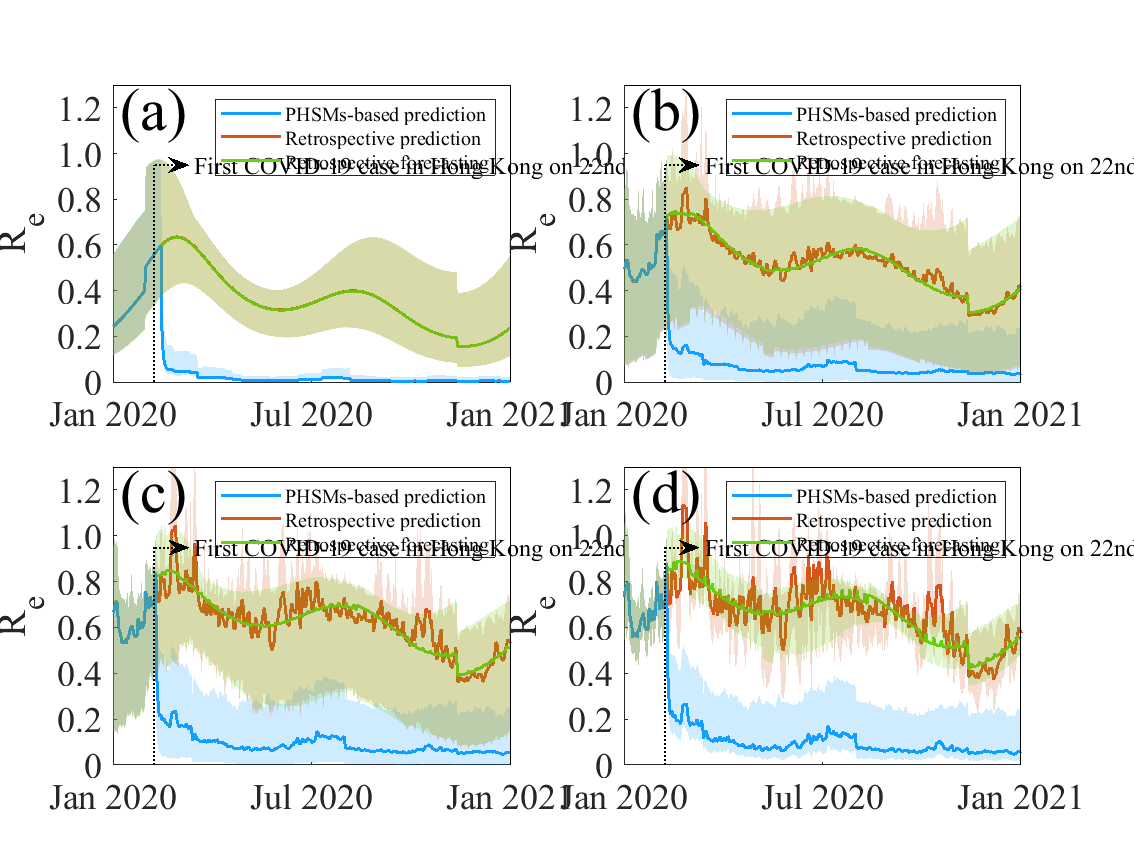

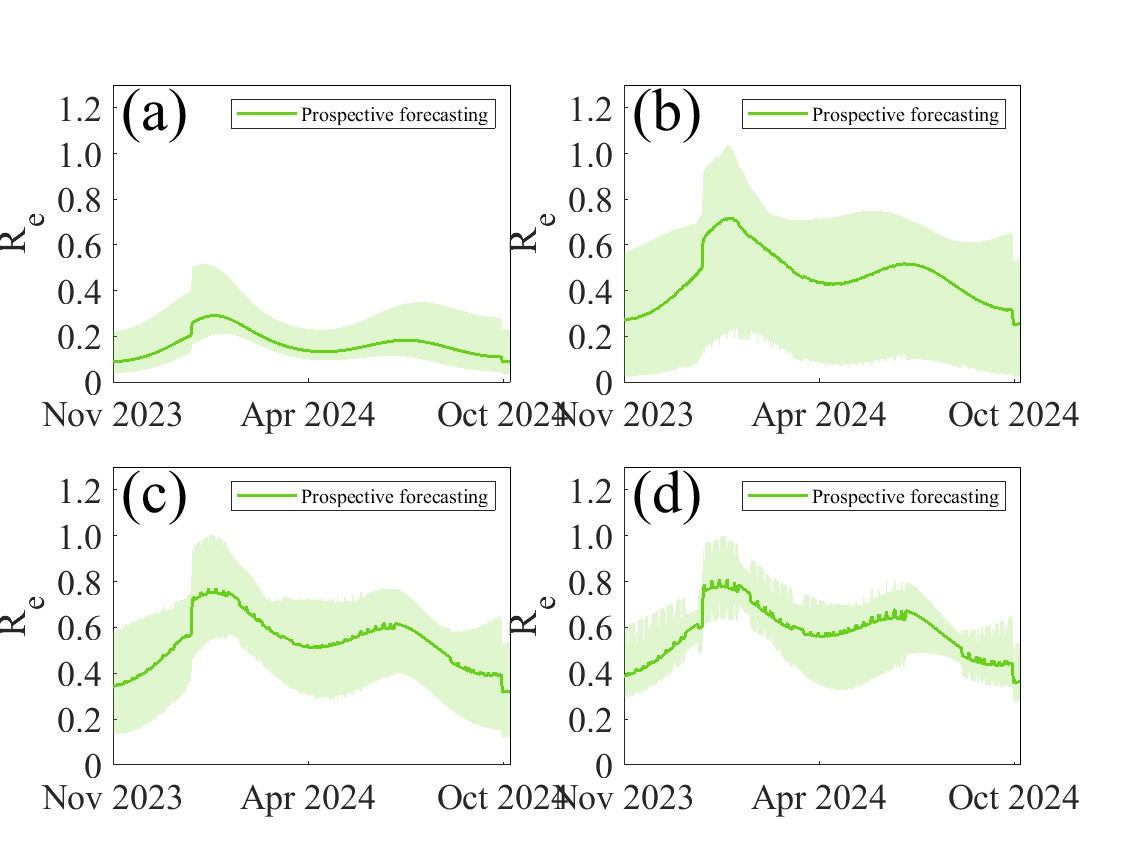



for row=1:numel(Model_scripts(model_number{ENmodel}))
axes(ha1(3));hold on;F_day1=1:394;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');ylabel(sprintf('Susceptibility'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[10:90:394]);
set(gca,'xticklabel',{'Dec 2019','Mar 2020','Jun 2020','Sep 2020','Dec 2020'},'XTickLabelRotation',0);xlim([10 375]);ylim([0.39 0.56]);
set(gca,'ytick',[0.4,0.45,0.5,0.55]);
set(gca,'yticklabel',{'0.4','0.45','0.5','0.55'});

[betaS,day1,meanbetaS]= modelCI(F_day1,R_newPI_LongS{5}');
[betaS1,day1,meanbetaS1]= modelCI(F_day1,R_newPI_LongCFSF{5}');
[betaS2,day1,meanbetaS2]= modelCI(F_day1,R_newPI_LongCFS{5}');

plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.07,0.62,1.00])
plot (F_day1,meanbetaS1,'LineWidth',1.5,'Color',[0.85,0.33,0.10])
plot (F_day1,meanbetaS2,'LineWidth',1.5,'Color',[0.39,0.83,0.07])

H_F1=fill(day1,betaS,[0.07,0.62,1.00],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
H_F1=fill(day1,betaS2,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
H_F1=fill(day1,betaS1,[0.85,0.33,0.10],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
plot([48 48],[0 0.47],':','color',[0 0 0],'LineWidth',1);
text(75,0.47,sprintf('First COVID-19 case in Hong Kong on 22nd Jan 2020'),'FontSize',10,'FontName','Times New Roman');
plotarrow(48,70,0.47,0.47)
box_off;
legend('PHSMs-based prediction','Retrospective prediction','Retrospective forecasting','color','none','Location','northeast')
set(legend,'color','none','Box', 'on'); 

axes(ha1(4));hold on;F_day1=1:394;
set(gcf,'unit','centimeters','position',[10 10 20 15]);
set(gca,'FontName','Times New Roman','FontSize',16);
xlabel('Time');ylabel(sprintf('Susceptibility'));
set(get(gca,'YLabel'),'FontSize',20);
set(get(gca,'XLabel'),'FontSize',20);
set(gca,'xtick',[20:90:414]);
set(gca,'xticklabel',{'Jun 2023', 'Sep 2023', 'Dec 2023', 'Mar 2024', 'Jun 2024'},'XTickLabelRotation',0);
[betaS,day1,meanbetaS]= modelCI(F_day1,P_newPI_LongS{5}');
plot (F_day1,meanbetaS,'LineWidth',1.5,'Color',[0.39,0.83,0.07])
H_F1=fill(day1,betaS,[0.39,0.83,0.07],'FaceAlpha',0.2);set(H_F1,{'LineStyle'},{'none'});
xlim([20 385]);ylim([0.2 0.5]);
set(gca,'ytick',[0.2,0.3,0.4,0.5]);
set(gca,'yticklabel',{'0.2','0.3','0.4','0.5'});
box_off;
legend('Prospective forecasting','color','none','Location','northeast')
set(legend,'color','none','Box', 'on'); 
end


scripts = [2010:1:2023];
for number = 1:numel(addressnew1)
   %  cd('C:\Users\Dong\SPH Dropbox\Wang Dong\PC\_4_modeling_end_1')
    cd ('E:\Dong\one_drive\OneDrive - The University Of Hong Kong\_4_modeling_end_log_normal')
    cd (addressnew1{number});

Unrecognized function or variable 'ha'.

    for jth=1:14
        close all
modelfun = @(d,th) f3(d(:,1),th,d);
load(sprintf('ABase_%d.mat',scripts(jth)));
chain1 = chain2; chain1(:,11)=0;
[CSCF,CRCF,CVCF,CSR,CRR,CVR] =deal([]); %CSR,CRR,CVR
[~,~,~,CSR,CVR,CRR]= mcmcpred(results2,chain2,s2chain2,[start:774]',modelfun,nsample);
[~,~,~,CSCF,CVCF,CRCF]= mcmcpred(results2,chain1,s2chain2,[start:774]',modelfun,nsample); 
save(sprintf('SRV_Comparetements_%d.mat',scripts(jth)),'CSCF','CRCF','CVCF','CSR','CRR','CVR')
% [~,~,~,CSCF,CVCF,CRCF]= mcmcpred(results2,chain1,s2chain2,[start:774]',modelfun,nsample); 
% save(sprintf('SRV_Comparetements_CF_%d.mat',scripts(jth)),'CSCF','CRCF','CVCF')
%F_effective_reproductive_number(chain2,scripts(job))
jth
    end
end
